# Seasonal Residential Heating System Design Using Sand Battery and Rooftop Photovoltaic Panels

This example shows how to setup a thermal energy storage (TES) that utilizes the solar energy stored in the summer to provide heating during the winters. You estimate the size of key components of the TES, improve the overall efficiency, and achieve a cost-effective solution.

Heating of residential buildings in cold countries is one of the main energy-consuming applications. According to the European Commission, residential heating and cooling accounts for up to 25 % of the total energy consumption in the European union (EU). 70% of this energy comes from non-renewable fossil fuel which leads to carbon emissions. Renewable power, like solar energy, is typically not adequately available during winters.

To implement a cost-effective solution, you can store the energy in form of sensible heat by heating the sand. This solution retains the thermal energy for long durations due to the low thermal conductivity of the sand. You dig a sufficiently large pit in the basement of the residential unit, lay the charging and discharging network in form of a resistive heater and air duct inside the pit, and fill up the pit with sand. The sand offers a cheap and clean heat energy storage. There are no chemical reactions involved in the process. 

This figure shows the schematic of the sand TES, or sand battery. The yellow coil represents the heater element that connects to a photovoltaic (PV) panel. The blue coil represents a metallic tube filled with a fluid. In times of abundant sunshine, the electric heater charges the sand battery by heating the sand. You extract this stored heat by circulating the fluid through the metallic tube. In this example, you blow air through the metallic tube using an air blower.

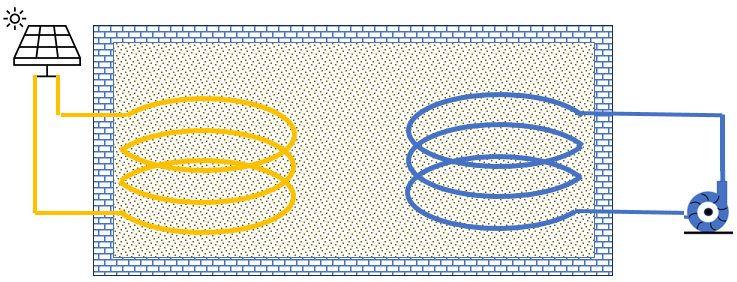

In this example, a Simscape™ custom component models the sand battery. To parameterize the custom battery component, set the number of electrical elements, pipe elements, and sand material properties. To learn more about the custom component, see [Sand Battery](matlab:open('../../Overview/html/blockDescriptionTES.html')).  

## Specify Requirements

In this example you learn how to design a system to maintain the temperature of the residential unit at a desired temperature value. The residential heating model comprises a rooftop PV panel for charging the thermal battery, a thermal battery for storing the excess renewable energy, a hot water tank, a heat exchanger (HEX), a pump, and an air blower.

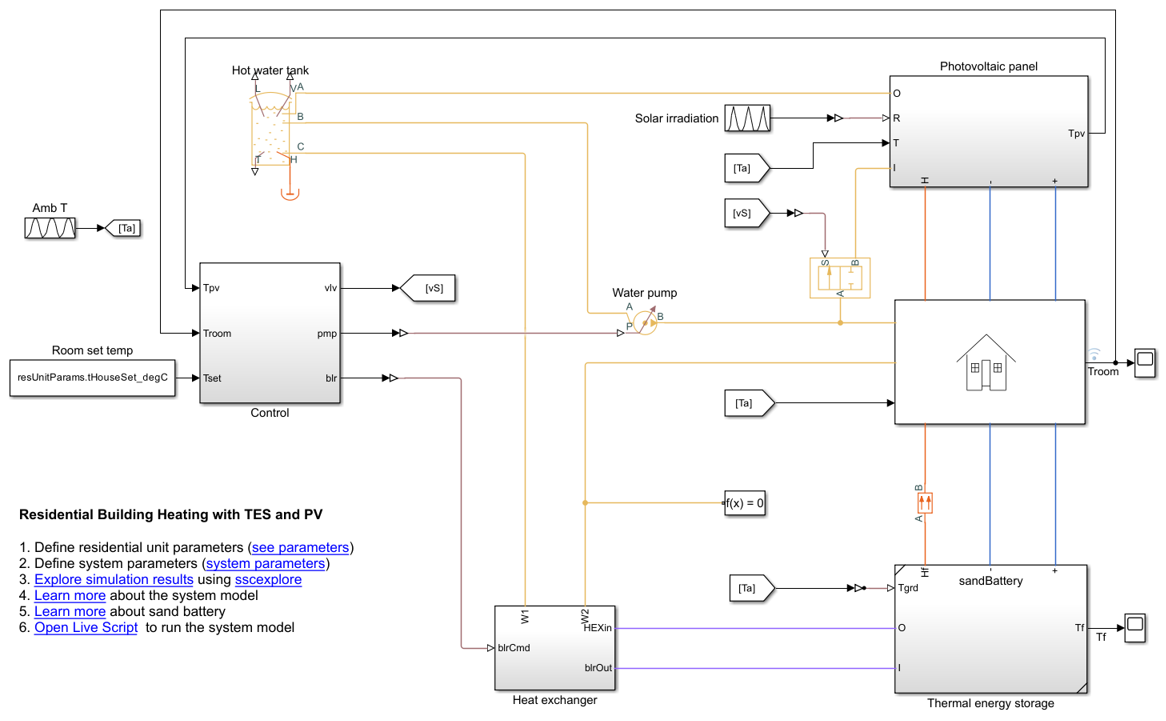

To learn more about the system model, see [Residential Building Heating with TES and PV](matlab:open('../../Overview/html/ResidentialBuildingTESandPVcell.html')).

Set the residential unit dimensions.

resUnit.dimResUnit = [10 10 5]; % Residential unit size (L W H) in meters

This example assumes you run high power-consuming appliances with PV power during daytime, such as washing machine, dishwasher, and oven. Set the typical monthly power consumption to 5kWh per day.

resUnit.monthlyPow = 30*5; % Monthly household power consumption covered by PV, kWh
resUnit.storageT_degC = 650; % Maximum sand temperature for heat storage

To reduce the yearly operating cost, set an economical room temperature setpoint for the year and limit the air flow to the sand battery.

resUnit.roomTemperatureSetpoint = 17; % Set room temperature to maintain, degC
maxBlowerFlow = 160 ; % Rated maximum flow of the air blower, cfm 

Set the design reference temperature for calculating the yearly heat loss from the building. If you set higher design reference temperature, the cost of the sand battery and PV unit increases.

resUnit.DesignRefTemperature = resUnit.roomTemperatureSetpoint; % Temperature, degC  

## Build System Model

In this example, a rooftop PV panel powers the residential unit and the sand battery stores the excess electrical energy from the PV panel. To heat the residential unit, the model uses a hot water tank. The air from the sand battery heats the water tank.

### **Load Weather Data**

Load the hourly ambient temperature and the direct normal irradiance (DNI) data for a year. 

ambientDataYearly = load("weatherAndSolarDataYear.mat");

The total photovoltaic power at any location is equal to the total AC power, in kWh, that a PV unit of 1 kW rated power generates at a specific location. To obtain this data, see [Global Solar Atlas](https://globalsolaratlas.info/map?c=59.165655,18.088074,10&s=59.345777,18.09494&m=site) ([check license](matlab:open('../../ScriptData/totalPhotoVoltaicPower.rights'))). Click on the point of interest in the map or search by entering the name of the location in the search field .

Load the monthly averaged total photovoltaic power. 

PVpowermonthly = load("totalPhotoVoltaicPower.mat");                                                    

To create a table of the monthly average of DNI and ambient temperature, use the `monthlyAveragedData` function.

monthlyAveragedData = extractWeatherAndSolarData(ambientDataYearly);
disp(monthlyAveragedData);

    Month    Avg Temperature(degC)    Average Total Solar Irradiation(W/m^2)
    _____    _____________________    ______________________________________

     Jan           -0.86562                            39.37                
     Feb            0.38516                           71.322                
     Mar             1.6101                           99.181                
     Apr             4.4771                              129                
     May             9.2883                           163.17                
     Jun             14.031                           188.57                
     Jul             15.193                           188.57                
     Aug             12.957                           163.17                
     Sep             10.646                              129                
     Oct              7.733                       

Plot the monthly averaged total photovoltaic power (Attribution to Global Solar Atlas) and DNI by using the `plotPVpowerAndIrr` function.

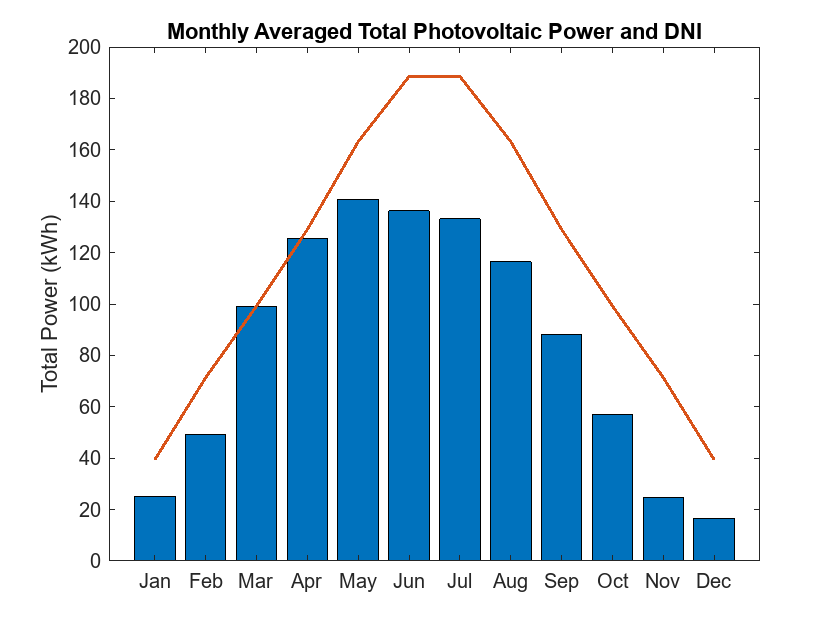

plotPVpowerAndIrr(PVpowermonthly,monthlyAveragedData)

Plot the monthly averaged ambient temperature by using the `plotMonthTemp` function.

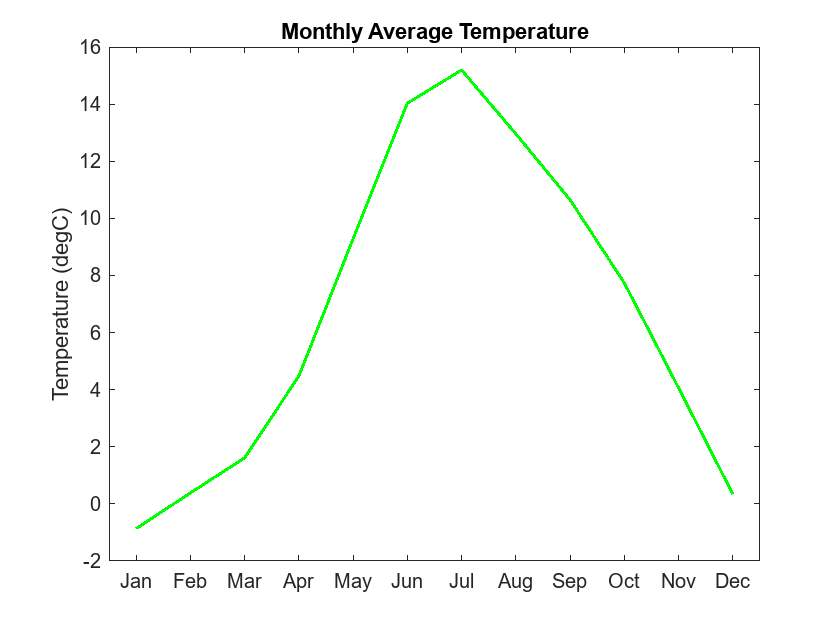

plotMonthTemp(monthlyAveragedData)

### Estimate Sand Battery Capacity 

Set the overall heat transfer coefficient for heat transfer between the residential unit air and ambient air. This coefficient comprises the internal air convection, the wall heat conduction, and the external air convection.

resUnit.overallHTC = 0.12; 

Specify the residential unit air ventilation as the hourly replacement fraction of the total air volume inside the house. 

resUnit.airVentilation = 0.7; % [1/h]

Estimate the required capacity of the sand battery, in Joule.

sandBatteryParams.heatCapacity = initialBatteryCapacityEstimate(resUnit.dimResUnit, ...
    resUnit.DesignRefTemperature, ...
    resUnit.overallHTC, resUnit.airVentilation, ...
    monthlyAveragedData);

This example assumes that the air pipe is a helical tube. Specify the initial estimate for the air pipe diameter, the helix outer diameter, and the pitch of the helical turns.

% Initial estimate for air pipe diameter (m)
sandBatteryParams.initPipeD = 0.1; 
% Initial estimate for coil diameter = 4 times pipe diameter (m)
sandBatteryParams.initCoilD = 4*sandBatteryParams.initPipeD;
% Initial estimate for pitch of the helical turns = 2 times pipe diameter (m)
sandBatteryParams.coilPitch = 2*sandBatteryParams.initPipeD;   

Estimate the battery volume by using the `getTESsize` function. The `getTESsize` function returns the required sand volume, the number of charging coils, and the number of air coils.

[sandBatteryParams.pitVol, sandBatteryParams.numCoils,sandBatteryParams.coilTurns] = ...
    getTESsize(sandBatteryParams.heatCapacity, resUnit.storageT_degC,...
                sandBatteryParams.initPipeD, sandBatteryParams.coilPitch,...
                sandBatteryParams.initCoilD,resUnit.DesignRefTemperature); 
disp(strcat("Required sand battery volume = ",num2str(sandBatteryParams.pitVol),"m^3,"));

Required sand battery volume = 47.0551m^3,


disp(strcat("which is ",num2str(100*sandBatteryParams.pitVol/prod(resUnit.dimResUnit)),...
            "% of volume of the residential unit"));

which is 9.411% of volume of the residential unit


To minimize the heat leakage to the ground, set the battery aspect ratio to a cubical shape.

sandBatteryParams.pitAspectRatio = 1; % Set pitAspectRatio = 1 for cubical pit
sandBatteryParams.pitDim = sandBatteryParams.pitVol^(1/3);
sandBatteryParams.pitDepth = (sandBatteryParams.pitVol)^(1/3)/...
                               sandBatteryParams.pitAspectRatio;

### Select Rooftop PV Panel

To support the residential unit and the charging of the sand battery, estimate the required PV power capacity. The required PV power capacity is the ratio between the total energy requirement and the total PV power. By definition, the total PV power, in kWh, is the average monthly output of an installed capacity of 1 kW PV power. 

% Conversion factor from Joules to kWh
Joules2kWh = 1/3.6e6; 
% Required PV power capacity to be installed
PVParams.PVcapacity_kW = (sandBatteryParams.heatCapacity*Joules2kWh + ...
                          12*resUnit.monthlyPow)/...
                          sum(PVpowermonthly.monthPVpow.("Total PV Power[kWh]")); 
disp(strcat('Required PV power = ',num2str(PVParams.PVcapacity_kW),' kW'))

Required PV power =11.5789 kW


The Solar Cell block in the model allows you to choose a pre-parameterized PV part. This example pre-parameterizes the Solar Cell block with the `Amerisolar:AS_6M_360W_PERC` part. You must open the block parameterization manager and store the values of the `PmW` and `Vm` variables for the part you choose.

PVParams.Pm = 355;  % Maximum power of single panel in Watts
PVParams.Vm = 38.8; % Corresponding voltage to PM in volts
PVParams.nSeries = 72; % Number of series connected cells in a single PV panel
                       % (provided in the supplier data sheet)
PVParams.dimPVpanel = [1.956 0.992]; % [L W] of the PV panel (m m)

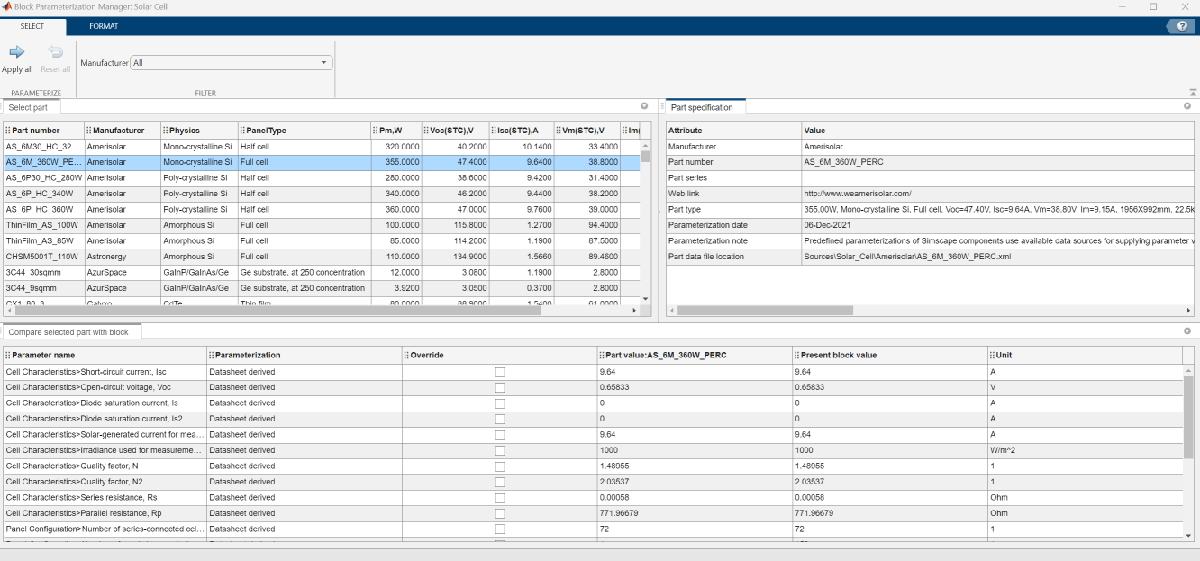

Estimate the required number of PV panels.

PVParams.numPVpanel = ceil(PVParams.PVcapacity_kW*1000/(PVParams.Pm));
disp(strcat("Number of PV panels = ",num2str(PVParams.numPVpanel)))

Number of PV panels = 33


Estimate the maximum number of PV panels that you can install on the roof of the residential unit.

% Fraction of roof area required to install the PV panels
PVParams.roofAreaCoverage = PVParams.numPVpanel*prod(PVParams.dimPVpanel)/...
                                (resUnit.dimResUnit(1)*resUnit.dimResUnit(2)); 
if PVParams.roofAreaCoverage > 1
    PVParams.numPVpanel = floor((resUnit.dimResUnit(1)*resUnit.dimResUnit(2))/...
                                  prod(PVParams.dimPVpanel));
    warning("Roof area is insufficient to accommodate required PV panels")
end

### Design Sand Battery Components

The thermal sand battery comprises a network of electric heater coils and tubular coils for air flow. To meet the residential unit heating requirement, you need to design following key components of the sand battery.

- Electric heating coil

- Tubular coils for air flow

- Thermal insulation to prevent heat loss to the ground

To design these components, calculate the required number of heating and air flow coils along the length and breadth of the battery.

sandBatteryParams.numCoilsX = ceil(sqrt(sandBatteryParams.numCoils/...
                                    sandBatteryParams.pitAspectRatio));
sandBatteryParams.numCoilsY = ceil(sandBatteryParams.pitAspectRatio*...
                                    sandBatteryParams.numCoilsX);

Set the depth of the coils in the vertical direction.

sandBatteryParams.airCoilDepth = sandBatteryParams.pitDepth;
sandBatteryParams.heaterCoilDepth = sandBatteryParams.pitDepth; 

To prevent a heater coil fault, set the heater element temperature limit for the current cutoff.

sandBatteryParams.heaterMaxT = 1000; % Heater element max temperature, degC

Estimate the heat conduction area, through which the stored heat is lost to the ground. To minimize the heat loss, you must insulate this area. This example assumes that the pit is not insulated towards the floor of the residential unit.

sandBatteryParams.groundConductionArea = sandBatteryParams.pitAspectRatio*...
    sandBatteryParams.pitDim^2 +...
    2*(1 + sandBatteryParams.pitAspectRatio)*...
    sandBatteryParams.pitDim*sandBatteryParams.pitDepth; 

Next, select the best combination of the three components to form the thermal battery. To display some of the readily available options for the components, load the `TEScomponentData` MAT file.

TEScomponentData = load("TEScomponentData.mat");
heaterInput = TEScomponentData.heater;
disp(heaterInput);

        Element Type         Electrical Resistance (ohm)    Unit Price (USD)
    _____________________    ___________________________    ________________

    {'Low Resistance'   }                10                        75       
    {'Medium Resistance'}                20                        85       
    {'High Resistance'  }                30                        95       



pipeInput = TEScomponentData.pipe;
disp(pipeInput);

    Pipe Grade    Pipe Diameter (m)    Unit Price (USD)
    __________    _________________    ________________

    {'Small' }           0.1                  1.5      
    {'Medium'}          0.15                 3.75      
    {'Large' }           0.2                    6      



insulationInput = TEScomponentData.insulation;
disp(insulationInput);

    Insulation Material    Thermal conductivity (W/m-K)    Sheet Thickness (m)    Unit Price (USD)
    ___________________    ____________________________    ___________________    ________________

     {'Mineral Wool'}                 0.038                        0.1                    2       
     {'PUF Sheet'   }                 0.025                        0.2                   10       
     {'Vacuum Panel'}                 0.003                       0.05                  160       



Run the system model for all possible combinations of the components and store the key performance criterion results in the `TEScombinationsResults` MAT file. The key performance criteria are: 

- Cost of the sand battery

- Heat stored in the battery

- Heat lost to the ground

- Durability of the heating coil. The durability is inversely proportional to the maximum coil temperature.

% Create all variable combinations
optionsSystemModel = fullFactorialDesign([length(TEScomponentData.heater.("Element Type")),...
                       length(TEScomponentData.pipe.("Pipe Grade")), ...
                        length(TEScomponentData.insulation.("Insulation Material"))]);
% set the runVerificationFlg to "false" for recursive run 
runVerificationFlg = false; 
% Simulation time in seconds
simTime = 24*3600;  

Load the precalculated simulation result table.

combinationsResult = load("TEScombinationsResults.mat");
resultTable = combinationsResult.optionsRunSummary;
disp(resultTable);

    Heater Element Type    Pipe Grade    Insulation Material    Sand Battery Cost (USD)    Heat Stored (J)    Heat Lost (J)    Heating Coil Temperature (degC)
    ___________________    __________    ___________________    _______________________    _______________    _____________    _______________________________

    "Low Resistance"        "Small"        "Mineral Wool"               406.52               9.4475e+07        1.1465e+07                   307.3             
    "Medium Resistance"     "Small"        "Mineral Wool"               442.62               3.4455e+07        1.1832e+07                  302.85             
    "High Resistance"       "Small"        "Mineral Wool"               478.73               1.3682e+07        1.1946e+07    

Select the combination that maximizes the heat storage and the durability and minimizes the cost and the heat loss to the ground. Select an aggregate best performing combination by averaging the normalized values of the key performance criteria.

% Select the most efficient and cost effective combination  
averagedNormal = (normc(resultTable.("Sand Battery Cost (USD)")) + ...
                  normc(resultTable.("Heat Lost (J)")) + ...
                  normc(resultTable.("Heating Coil Temperature (degC)")) +...
                  (normc(resultTable.("Heat Stored (J)")).^-1))/4;
[minvalue,  minimaDesignInd] = min(averagedNormal);
disp("Selected design combination")

Selected design combination


SelectedDesign = resultTable(minimaDesignInd,:);
disp(SelectedDesign);

    Heater Element Type    Pipe Grade    Insulation Material    Sand Battery Cost (USD)    Heat Stored (J)    Heat Lost (J)    Heating Coil Temperature (degC)
    ___________________    __________    ___________________    _______________________    _______________    _____________    _______________________________

     "Low Resistance"       "Small"          "PUF Sheet"                927.87               1.0279e+08        3.4235e+06                   307.3             



## Verify Design 

You must verify your battery design with a year-long simulation to ensure that it meets the requirements. You start the simulation with zero heat stored inside the sand battery. As a starting point of the simulation, you select a date and time of the year with the highest solar irradiation. The `verificationResults` MAT file stores the results for a year-long simulation.

To run the verification step, at the MATLAB® Command Window, run this command:

To verify the system design, plot the room temperature. First, load the year-long simulation data from the `verificationResults` MAT file. 

verificationResults = load('verificationResults.mat');

Set the date and time at the start of the simulation. 

[maxIrradiation, maxInd] = max(ambientDataYearly.hourlyData.(...
                                 "Total Solar Irradiation(W/m^2)"));
startDateTime = ambientDataYearly.hourlyData.("Date Time")(maxInd,:);
simDateTime = startDateTime + seconds(verificationResults.time);
simAmbientT = [ambientDataYearly.hourlyData.("Ambient Temperature(degC)")(maxInd:end,:);...
               ambientDataYearly.hourlyData.("Ambient Temperature(degC)")(1:maxInd-1,:)];

Plot the room and ambient temperature for the year.

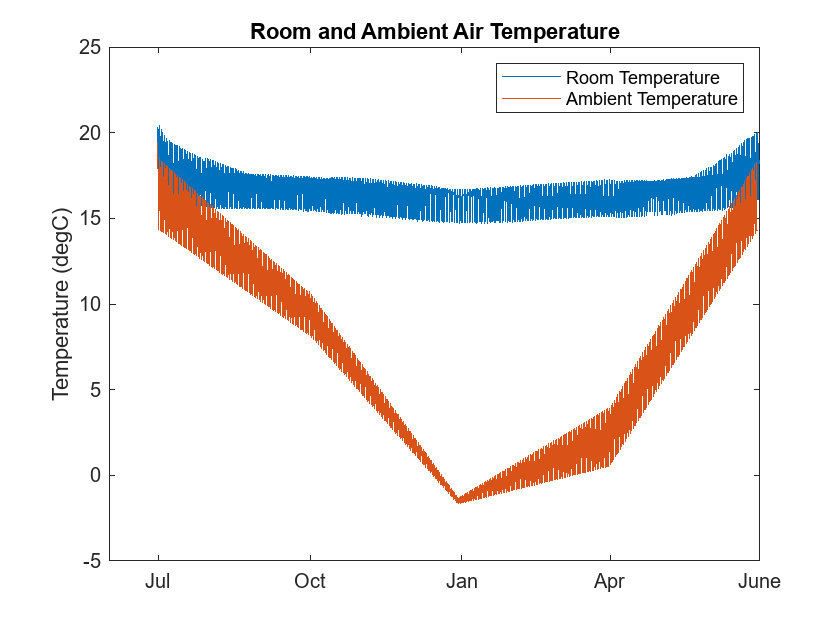

plot (simDateTime ,(verificationResults.avgRoomTemp)-273.15);
hold on
avgWindow = 24*0.6/(ambientDataYearly.hourlyData.("Time(hrs)")(2,1) - ...
                ambientDataYearly.hourlyData.("Time(hrs)")(1,1));
plot(startDateTime + hours(movmean(ambientDataYearly.hourlyData.("Time(hrs)"), ...
      avgWindow)), movmean(simAmbientT, avgWindow))
monthsForPlotting = {'Jul','Oct','Jan','Apr','June'};
title("Room and Ambient Air Temperature");
xticklabels(monthsForPlotting);
ylabel("Temperature (degC)");
hold off
legend(["Room Temperature", "Ambient Temperature"])

## Calculate Return on Investment

To assess the financial viability of the residential unit heating system, calculate the overall system installation cost,


$${\textrm{IC}=\;P}_{\textrm{pv}} +P_{\textrm{TES}} +P_{\textrm{wp}} +P_{\textrm{HEX}} +P_{\textrm{ab}} \;,$$


where:

- IC is the system installation cost. In this example, the material cost includes the labor charges to install the hardware.

- $P_{\textrm{pv}}$ is the price of the PV panels.

- $P_{\textrm{TES}}$ is the cost of the sand battery. You can obtain this value from `resultTable` in the previous section. You can neglect the cost of the sand because you can use waste sand in the sand battery.

- $P_{\textrm{ab}}$ is the price of the air blower.

- $P_{\textrm{wp}}$ is the price of the water pump.

- $P_{\textrm{HEX}}$ is the price of the heat exchanger.

 Estimate the yearly cost of electricity to operate the residential unit heating system,

$\textrm{OC}=\frac{2\ldotp 77778e-7\times H{\times P}_e }{\textrm{COP}}$,

where:

- COP is the coefficient of performance of the residential heating system with the sand battery, and is equal to $\frac{{\textrm{Pow}}_{\textrm{House}} }{{\textrm{Pow}}_{\textrm{pmp}} }$.

- $\textrm{OC}$ is the per-year operating cost of the house heating system using sand battery.

- $P_e$ is the average per-unit electricity price.

- ${\textrm{Pow}}_{\textrm{House}}$ is the average heating power that the sand battery supplies to the residential unit. 

- ${\textrm{Pow}}_{\textrm{pmp}}$ is the average power consumption for running the air blower and the water pump.

If you burn gas to heat the residential unit instead of using a PV sand battery system, your net yearly saving is the difference between the gas cost and the operating cost of the residential unit heating system,

 ${S=P}_G \times \frac{H}{{\textrm{CV}}_G \times \eta }-\textrm{OC}$,

where:

- $P_G$ is the average per-liter gas price.

- $H$ is the yearly heat that the sand battery supplies.

- ${\textrm{CV}}_G$ is the specific calorific value of the gas.

- $\eta$ is the water heater efficiency.

To obtain the operating years to achieve the break even, solve this equation for `t`:

$\textrm{IC}\times {\left(1+r\right)}^t -S\times \left(1+r\right)\times \left\lbrace {\left(1+r\right)}^t -1\right\rbrace /r=0$,

where `t` is the time in years and `r` is the yearly interest rate.

Calculate the COP of the residential heating system with the sand battery.

verify.pumpEnergy = trapz(verificationResults.time, verificationResults.pumpPower);
verify.totalResUnitHeat = trapz(verificationResults.time, verificationResults.heatHouse);
verify.COP = verify.totalResUnitHeat/verify.pumpEnergy; 

Use the `calculateCost` function to calculate the installation cost, yearly operating cost, and yearly savings. 

[verify.installationCost, verify.yrlySavings] = ...
   calcSystemCostAndSaving(resultTable.("Sand Battery Cost (USD)")(minimaDesignInd),...
   verify.pumpEnergy, PVParams.numPVpanel, verify.totalResUnitHeat);

Specify the yearly interest rate percentage.

verify.intRate = 5.5;

Specify the time in number of years.

verify.years = linspace(0, 20, 101);

Calculate the system cost recovery time.

verify.costRecovery = verify.installationCost*(1+(verify.intRate/100)).^verify.years -...
                       verify.yrlySavings*((1+(verify.intRate/100)).^verify.years-1)*...
                       (1+(verify.intRate/100))/(verify.intRate/100);

Plot the installation cost recovery with time. 

yearsBreakEven = fitPolyAndSolve(verify.years,verify.costRecovery)

yearsBreakEven = 8.9600

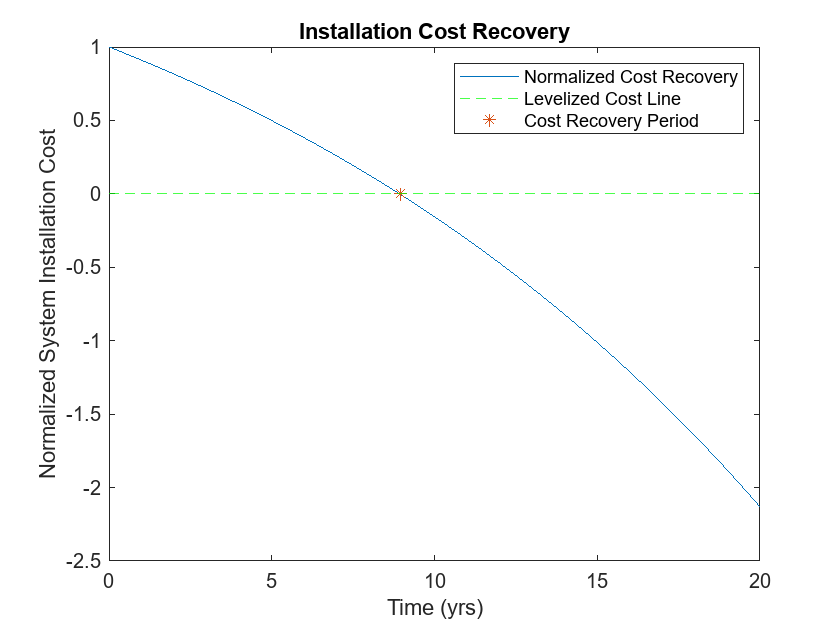

plot(verify.years, verify.costRecovery/verify.installationCost);
xlabel("Time (yrs)");
ylabel("Normalized System Installation Cost");
hold on 
title("Installation Cost Recovery")
yline(0, '--g')
hold on
plot(yearsBreakEven,0,'*')
hold off
legend("Normalized Cost Recovery","Levelized Cost Line","Cost Recovery Period")

You meet the break even for installation cost at the intersection between the cost function and the time axis. As this time is sufficiently smaller than the life of the sand battery and the residential unit, this is a cost-effective environment friendly solution for the heating of the residential buildings.

## Appendix

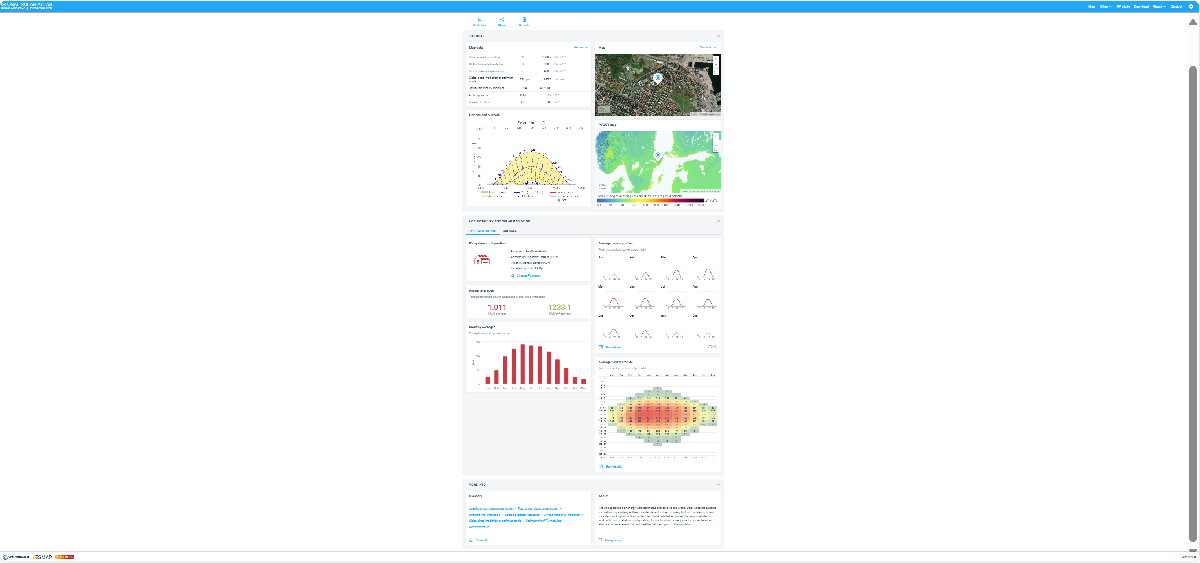

[Data/information/map] obtained from the “Global Solar Atlas 2.0, a free, web-based application is developed and operated by the company Solargis s.r.o. on behalf of the World Bank Group, utilizing Solargis data, with funding provided by the Energy Sector Management Assistance Program (ESMAP). For additional information: [https://globalsolaratlas.info](https://globalsolaratlas.info/)